# Read Images

M = 1018;
for k = 0:M
   if k<10
       jpgFilename = sprintf('/images/snake_color/snake_000%d.png', k);
   elseif k<100
       jpgFilename = sprintf('/images/snake_color/snake_00%d.png', k);
   elseif k<1000
       jpgFilename = sprintf('/images/snake_color/snake_0%d.png', k);
   else
       jpgFilename = sprintf('/images/snake_color/snake_%d.png', k);
   end
  fullFileName = fullfile('D:\AMINE\Dev\particle_filter_snake', jpgFilename);
  if exist(fullFileName, 'file')
    imageData_{k+1} = imread(fullFileName);
  else
    warningMessage = sprintf('Warning: image file does not exist:\n%s', fullFileName);
    uiwait(warndlg(warningMessage));
  end
%  imshow(imageData);
end

# Algorithm

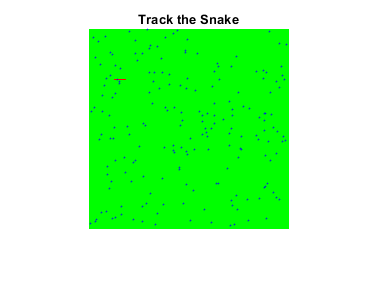

Ns = 200;
% Making Video
v= VideoWriter('PF2.avi');
open(v);
figure
imshow(imageData_{1})
title('Track the Snake')
hold on
for i = 1: Ns
    x_t(i) = {[floor(200*rand) floor(200*rand)]};
    plot(x_t{i}(1,1),x_t{i}(1,2),'.b','MarkerSize',2)
end

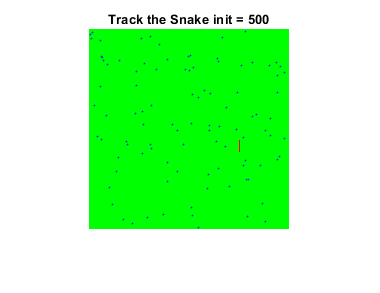

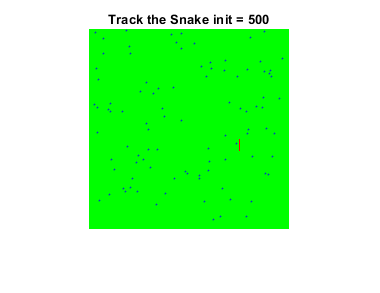

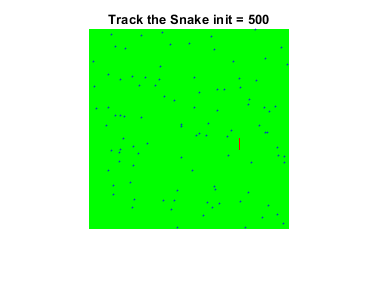

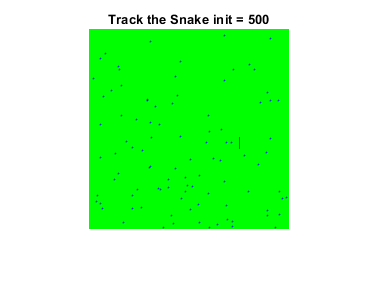

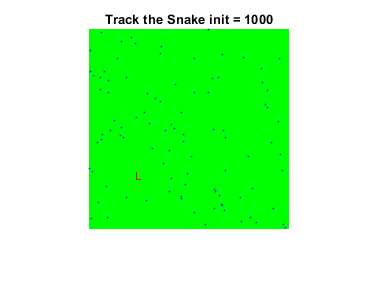

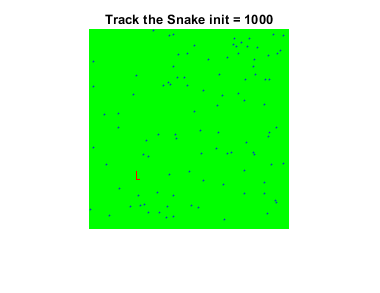

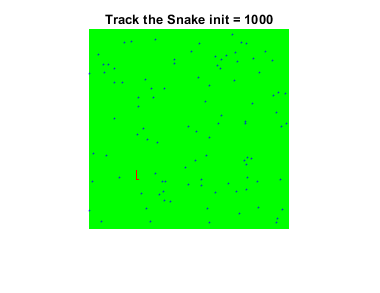

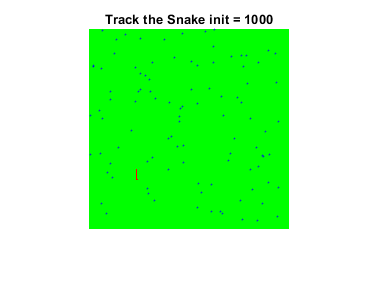

p = x_t;
init = 50;
%for init = [1 10 50 100 500 1000] 
    for j = init : M 
        p = Particle_filter(p,measure(imageData_{j}),Ns);
    %     mm{j}=p;
        figure
        imshow(imageData_{j})
        ttl = ['Track the Snake init = ' num2str(init)];
        title(ttl);
        hold on
        for i = 1: Ns
            plot(p{i}(1,2),p{i}(1,1),'.b','MarkerSize',2)
        end
        hold off
        frame = getframe(gcf);
        writeVideo(v,frame);
    end

%end
close(v)

## Particle Filter Algorithm

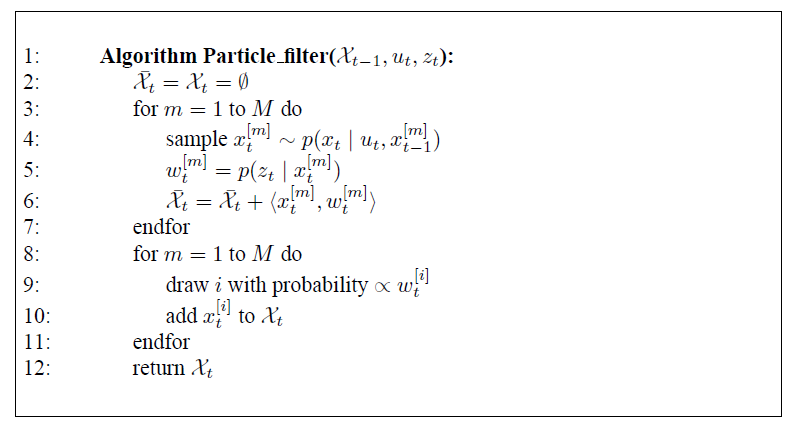

`% Inputs:`

`% X  = function handle to process equation`

`% u   = observation vector at time k (column vector)`

`% z   = structure with the following fields`

`% Ns   = structure with the following fields`

`% Outputs:`

`% xhk   = estimated state`

function p = Particle_filter(x_init,z,Ns)
% Intialization
%X_dash = 0;
x_t = x_init;
%p = {[0 0]};
w_t = ones(1,Ns);
snake = 0;ii=1;
    for m = 1 : Ns
        % Update
        x_t{m} = move(x_t{m});
        % Correction
        w_t(m) = weight(x_t{m},z);
        if w_t(m) == 1
            snake(1,ii) = m;
            ii = ii + 1;
        end
      p{m} = w_t(m)*x_t{m};
    %  p{m} = x_t{m};
    end
    % Resampling
    for m = 1 : Ns/2 
        if w_t(m) == 0 && snake(1,1) > 0
        [~,no] = size(snake)   ; 
        random = ceil(no*rand)  ;  
        p{m} = move(p{snake(1,random)});
        elseif w_t(m) == 1
        p{m} = p{m};
        else
            p{m} = [floor(200*rand) floor(200*rand)];
        end
        
    end
end 

# Measurment

function z = measure(image)
    [m,n,l]= size(image);
    z = image(:,:,1) == 255*ones(m,n);
end

# Action (For this Ex no action)


% function u = action(inti,img0,img1)
% if inti == 1
%     u = [1 0];
% else
%     
% end
% 
% end

# particles weight

function w = weight(p,z)
% figure
% imshow(z)
% pause
% p(1,2)
% pause
p = abs(p);
if p(1,1) == 0 || p(1,1) > 200 
    p(1,1) = 1;
end
if p(1,2) == 0 || p(1,2) > 200
    p(1,2) = 1;
end
    if z(p(1,1),p(1,2)) == 1
        w = 1;
    else
        w = 0;
    end
    
end

# Move Particle

function x = move(x_t)
random = ceil(4*rand);
    if random == 1 
        x = x_t + [1 0];
    elseif random == 2
        x = x_t + [0 1];
    elseif random == 3
        x = x_t + [-1 0];
    else 
        x = x_t + [0 -1];
    end
end